Starting point infeasible; using x0 = At*inv(AAt)*y.
Iteration = 1, tau = 1.527e+01, Primal = 1.167e+04, PDGap = 2.145e+04, Dual res = 1.287e+02, Primal res = 6.484e-12
                  H11p condition number = 1.268e-04
Iteration = 2, tau = 3.159e+01, Primal = 8.248e+03, PDGap = 1.037e+04, Dual res = 4.196e+01, Primal res = 9.915e-10
                  H11p condition number = 9.497e-07
Iteration = 3, tau = 8.019e+01, Primal = 4.048e+03, PDGap = 4.086e+03, Dual res = 9.627e+00, Primal res = 3.369e-10
                  H11p condition number = 1.417e-06
Iteration = 4, tau = 1.892e+02, Primal = 1.979e+03, PDGap = 1.732e+03, Dual res = 3.228e+00, Primal res = 1.803e-10
                  H11p condition number = 3.014e-07
Iteration = 5, tau = 3.966e+02, Primal = 1.179e+03, PDGap = 8.263e+02, Dual res = 1.331e+00, Primal res = 1.051e-10
                  H11p condition number = 9.027e-08
Iteration = 6, tau = 7.562e+02, Primal = 8.489e+02, PDGap = 4.334e+02, Dual res = 6.249e-01, Primal res = 7

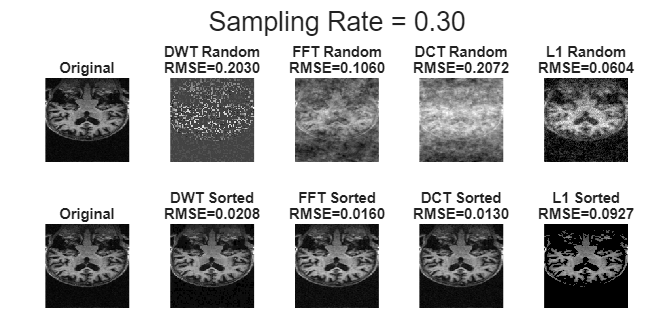

Starting point infeasible; using x0 = At*inv(AAt)*y.
Iteration = 1, tau = 1.697e+01, Primal = 1.513e+04, PDGap = 1.931e+04, Dual res = 4.025e+01, Primal res = 6.225e-12
                  H11p condition number = 2.129e-05
Iteration = 2, tau = 4.874e+01, Primal = 6.625e+03, PDGap = 6.723e+03, Dual res = 6.382e+00, Primal res = 7.456e-10
                  H11p condition number = 1.290e-07
Iteration = 3, tau = 1.884e+02, Primal = 2.033e+03, PDGap = 1.739e+03, Dual res = 9.330e-01, Primal res = 1.224e-10
                  H11p condition number = 1.657e-07
Iteration = 4, tau = 4.140e+02, Primal = 1.214e+03, PDGap = 7.914e+02, Dual res = 3.661e-01, Primal res = 5.241e-11
                  H11p condition number = 2.439e-08
Iteration = 5, tau = 7.821e+02, Primal = 9.220e+02, PDGap = 4.190e+02, Dual res = 1.744e-01, Primal res = 2.635e-11
                  H11p condition number = 7.539e-09
Iteration = 6, tau = 1.572e+03, Primal = 7.707e+02, PDGap = 2.084e+02, Dual res = 7.699e-02, Primal res = 2

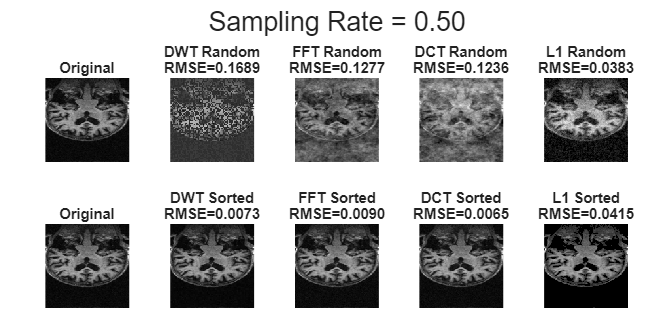

Starting point infeasible; using x0 = At*inv(AAt)*y.
Iteration = 1, tau = 2.154e+01, Primal = 1.446e+04, PDGap = 1.521e+04, Dual res = 9.469e+00, Primal res = 5.080e-12
                  H11p condition number = 5.422e-06
Iteration = 2, tau = 8.548e+01, Primal = 4.044e+03, PDGap = 3.834e+03, Dual res = 1.201e+00, Primal res = 3.516e-10
                  H11p condition number = 2.255e-08
Iteration = 3, tau = 2.578e+02, Primal = 1.663e+03, PDGap = 1.271e+03, Dual res = 3.038e-01, Primal res = 9.007e-11
                  H11p condition number = 1.923e-08
Iteration = 4, tau = 6.035e+02, Primal = 1.068e+03, PDGap = 5.430e+02, Dual res = 1.102e-01, Primal res = 3.567e-11
                  H11p condition number = 3.704e-09
Iteration = 5, tau = 1.194e+03, Primal = 8.818e+02, PDGap = 2.743e+02, Dual res = 4.962e-02, Primal res = 3.264e-11
                  H11p condition number = 1.034e-09
Iteration = 6, tau = 2.227e+03, Primal = 8.047e+02, PDGap = 1.472e+02, Dual res = 2.406e-02, Primal res = 3

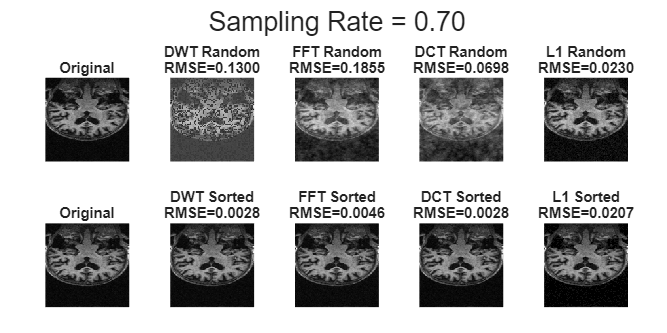

tic
clc;
clear;
close all;

imageFolder = "C:\Users\udayc\OneDrive\文件\MFC DATASET\GAN-Traning Images";
imageFiles  = dir(fullfile(imageFolder,'*.jpg'));

imagePath = fullfile(imageFolder,imageFiles(1).name);

A = imread(imagePath);

if ndims(A)==3
    A = rgb2gray(A);
end

A = im2double(mat2gray(A));
A = imresize(A,[128 128]);


samplingRates = [0.3 0.5 0.7];


names = ["DWT Random","FFT Random","DCT Random","L1 Random",...
         "DWT Sorted","FFT Sorted","DCT Sorted","L1 Sorted"];


RMSE = zeros(length(samplingRates),8);
PSNR = zeros(length(samplingRates),8);
SSIM = zeros(length(samplingRates),8);

for s = 1:length(samplingRates)

samplingRate = samplingRates(s);

figure('Name',sprintf('Sampling Rate %.2f',samplingRate),...
'Units','normalized','Position',[0.05 0.1 0.9 0.8])

tiledlayout(2,5,'Padding','compact','TileSpacing','compact')

sgtitle(sprintf('Sampling Rate = %.2f',samplingRate),'FontSize',16)


nexttile
imshow(A,[])
title('Original')

%% ================= DWT RANDOM =================
[coeffs,book] = wavedec2(A,1,'haar');

M = length(coeffs);
N = round(M * samplingRate);

idx = randsample(1:M,N);

recCoeff = zeros(size(coeffs));
recCoeff(idx) = coeffs(idx);

recon = waverec2(recCoeff,book,'haar');

RMSE(s,1)=sqrt(immse(A,recon));
PSNR(s,1)=psnr(recon,A);
SSIM(s,1)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('DWT Random\nRMSE=%.4f',RMSE(s,1)))

%% ================= FFT RANDOM =================
F = fft2(A);

M = numel(F);
N = round(M * samplingRate);

idx = randsample(1:M,N);

recF = zeros(size(F));
recF(idx) = F(idx);

recon = real(ifft2(recF));

RMSE(s,2)=sqrt(immse(A,recon));
PSNR(s,2)=psnr(recon,A);
SSIM(s,2)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('FFT Random\nRMSE=%.4f',RMSE(s,2)))

%% ================= DCT RANDOM =================
D = dct2(A);

M = numel(D);
N = round(M * samplingRate);

idx = randsample(1:M,N);

mask = zeros(size(D));
mask(idx)=D(idx);

recon = idct2(mask);

RMSE(s,3)=sqrt(immse(A,recon));
PSNR(s,3)=psnr(recon,A);
SSIM(s,3)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('DCT Random\nRMSE=%.4f',RMSE(s,3)))

%% ================= L1 RANDOM =================

signal = A(:);
m = round(length(signal) * samplingRate);

Phi = randn(m,length(signal)) / sqrt(m);
y = Phi * signal;

Theta = Phi * idct(eye(length(signal)));

s1 = l1eq_pd(zeros(length(signal),1),Theta,Theta',y,1e-6,26);

recoveredSignal = idct(s1);
recon = reshape(recoveredSignal,size(A));

recon = max(min(recon,1),0);

RMSE(s,4)=sqrt(immse(A,recon));
PSNR(s,4)=psnr(recon,A);
SSIM(s,4)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('L1 Random\nRMSE=%.4f',RMSE(s,4)))

%% ORIGINAL SECOND ROW
nexttile
imshow(A,[])
title('Original')

%% ================= DWT SORTED =================
[~,idx]=sort(abs(coeffs),'descend');

mask=zeros(size(coeffs));
mask(idx(1:N))=coeffs(idx(1:N));

recon = waverec2(mask,book,'haar');

RMSE(s,5)=sqrt(immse(A,recon));
PSNR(s,5)=psnr(recon,A);
SSIM(s,5)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('DWT Sorted\nRMSE=%.4f',RMSE(s,5)))

%% ================= FFT SORTED =================
[~,idx]=sort(abs(F(:)),'descend');

mask=zeros(size(F));
mask(idx(1:N))=F(idx(1:N));

recon = real(ifft2(mask));

RMSE(s,6)=sqrt(immse(A,recon));
PSNR(s,6)=psnr(recon,A);
SSIM(s,6)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('FFT Sorted\nRMSE=%.4f',RMSE(s,6)))

%% ================= DCT SORTED =================
[~,idx]=sort(abs(D(:)),'descend');

mask=zeros(size(D));
mask(idx(1:N))=D(idx(1:N));

recon = idct2(mask);

RMSE(s,7)=sqrt(immse(A,recon));
PSNR(s,7)=psnr(recon,A);
SSIM(s,7)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('DCT Sorted\nRMSE=%.4f',RMSE(s,7)))

%% ================= L1 SORTED =================

[~,idx]=sort(abs(signal),'descend');

mask=zeros(size(signal));
mask(idx(1:m))=signal(idx(1:m));

recon = reshape(mask,size(A));

RMSE(s,8)=sqrt(immse(A,recon));
PSNR(s,8)=psnr(recon,A);
SSIM(s,8)=ssim(recon,A);

nexttile
imshow(recon,[])
title(sprintf('L1 Sorted\nRMSE=%.4f',RMSE(s,8)))

end

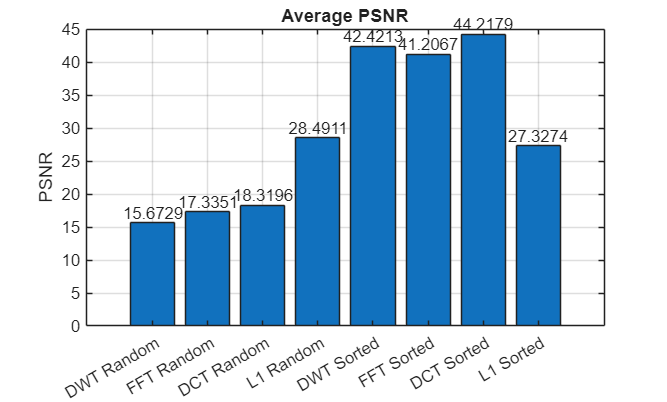


figure
b = bar(avgPSNR);
set(gca,'XTickLabel',names)

ylabel('PSNR')
title('Average PSNR')
grid on

xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(b.YData,4));

text(xtips,ytips,labels,...
    'HorizontalAlignment','center',...
    'VerticalAlignment','bottom',...
    'FontSize',10)

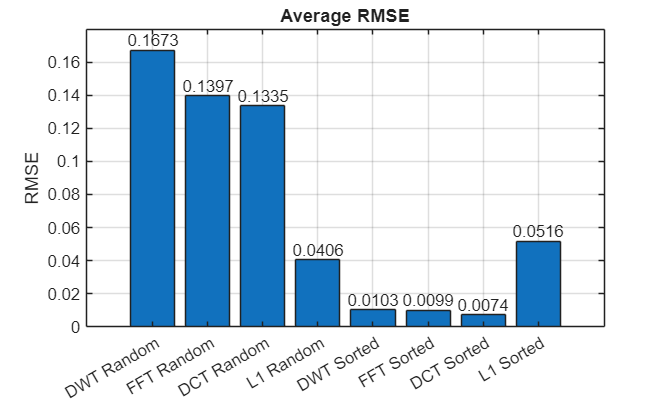


figure
b = bar(avgRMSE);
set(gca,'XTickLabel',names)

ylabel('RMSE')
title('Average RMSE')
grid on

xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(b.YData,4));

text(xtips,ytips,labels,...
    'HorizontalAlignment','center',...
    'VerticalAlignment','bottom',...
    'FontSize',10)

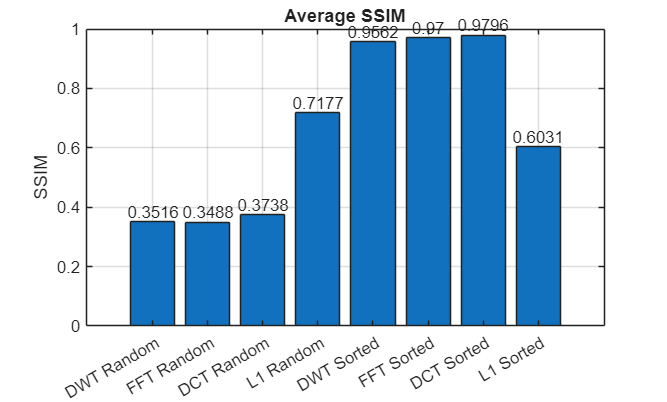


figure
b = bar(avgSSIM);
set(gca,'XTickLabel',names)

ylabel('SSIM')
title('Average SSIM')
grid on

xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(b.YData,4));

text(xtips,ytips,labels,...
    'HorizontalAlignment','center',...
    'VerticalAlignment','bottom',...
    'FontSize',10)

toc

Elapsed time is 2793.387248 seconds.
